# Two-site energy variance

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will complete the code for computing the two-site energy variance, following the recipe given in Sec. IV of Gleis2022 [[A. Gleis, J.-W. Li, and J. von Delft, arXiv:2207.13161 (2022)](https://arxiv.org/abs/2207.13161)]. (Note that the two-site variance approach was first proposed in Hubig2018 [[C. Hubig, J. Haegeman, and U. Schollwöck, Phys. Rev. B **97**, 045125 (2018)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.97.045125)].) Then we will use the variance to extrapolate the ground-state energy from the DMRG calculations, to estimate the "numerically exact" value of the ground-state energy in the limit of zero truncation.

## Exercise (a): Complete the function for the two-site energy variance

There is a function `varE_2site_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

You can check your implementation by running the following script, where the two-site variance and its individual terms are computed for the 1-site DMRG ground-state search result.

As always, we consider the XY chain. We first set parameters and define the MPO Hamiltonian.

clear

% system parameter
J = -1; % coupling strength
L = 40; % number of sites in a chain
E0_exact = (-J)*(0.5 - (1/2/sin(pi/2/(L+1)))); % exact value

% DMRG parameters
Nkeep = 20;
Nsweep = 4; % number of pairs of left+right sweeps

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

As the initial state of the variational optimization within the DMRG, we use the result of the iterative diagonalization.

Minit = cell(1,L);

% tensors for the vaccum (i.e., dummy leg)
Hprev = 1; % initialize Hamiltonian with 1, as we will use MPO
Aprev = 1; % identity tensor for the dummy leg

for itN = (1:L)
    % add new site
    Anow = getIdentity(Aprev,2,I,2,[1 3 2]);
    Hnow = updateLeft(Hprev,3,Anow,Hs{itN},4,Anow);

    Hmat = Hnow(:,:,1);
    [V,D] = eig((Hmat+Hmat')/2);
    [D,ids] = sort(diag(D),'ascend');
    if itN < L
        Ntr = min([numel(D);Nkeep]);
    else
        Ntr = 1;
    end
    V = V(:,ids(1:Ntr));
    
    Anow = contract(Anow,3,2,V,2,1,[1 3 2]);

    Minit{itN} = Anow;
    
    Hprev = contract(Hnow,3,2,V,2,1);
    Hprev = contract(V',2,2,Hprev,3,1,[1 3 2]);
    Aprev = Anow;
end

Run the 1-site DMRG.

[M,E0,Eiter] = DMRG_GS_1site(Minit,Hs,Nkeep,Nsweep);

22-11-05 21:45:17 | Single-site DMRG: ground state search
22-11-05 21:45:17 | # of sites = 40, Nkeep = 20, # of sweeps = 4 x 2
22-11-05 21:45:17 | Sweep #1/8 (right -> left) : Energy = -12.5537
22-11-05 21:45:17 | Sweep #2/8 (left -> right) : Energy = -12.55387
22-11-05 21:45:17 | Sweep #3/8 (right -> left) : Energy = -12.55387
22-11-05 21:45:17 | Sweep #4/8 (left -> right) : Energy = -12.55387
22-11-05 21:45:18 | Sweep #5/8 (right -> left) : Energy = -12.55387
22-11-05 21:45:18 | Sweep #6/8 (left -> right) : Energy = -12.55387
22-11-05 21:45:18 | Sweep #7/8 (right -> left) : Energy = -12.55387
22-11-05 21:45:18 | Sweep #8/8 (left -> right) : Energy = -12.55387
Elapsed time: 1.067s, CPU time: 9.45s, Avg # of cores: 8.86


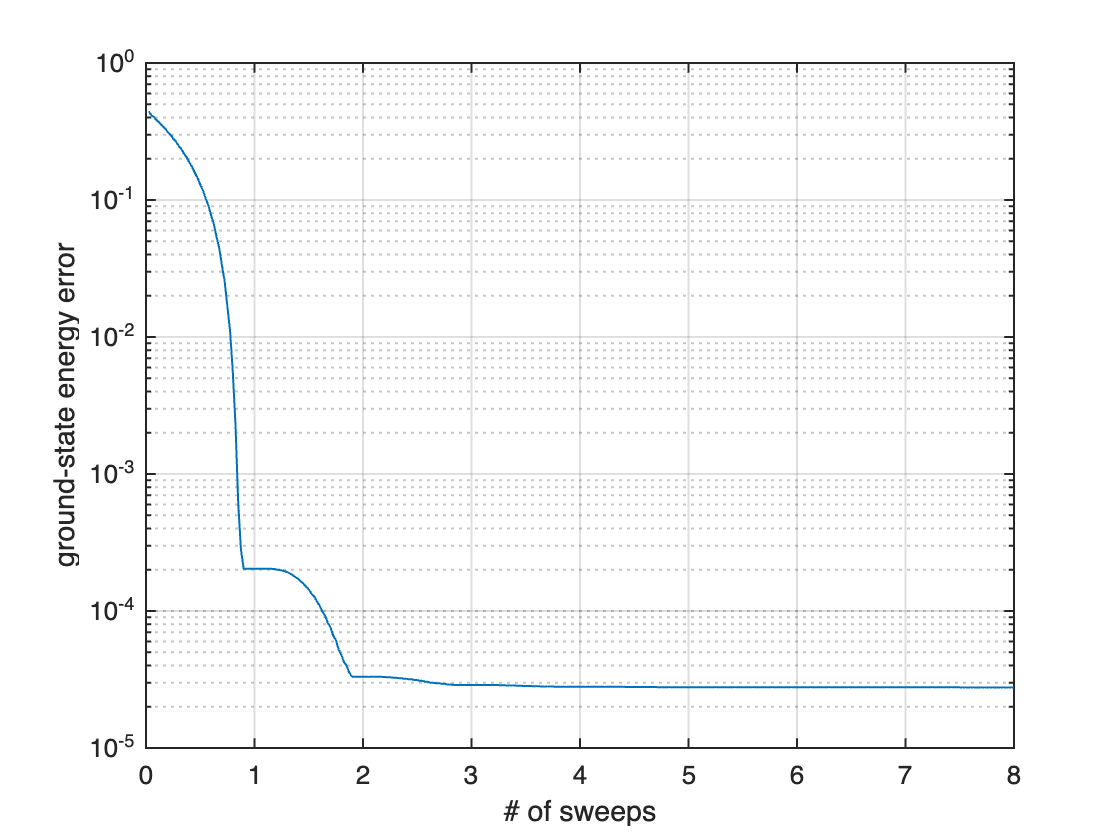


figure;
semilogy((1:numel(Eiter))/L,Eiter(:)-E0_exact,'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1);
xlim([0 2*Nsweep]);
grid on;
xlabel('# of sweeps');
ylabel('ground-state energy error');

The error of the numerical ground-state energy is of $O(10^{-5})$.

disp(E0 - E0_exact);

   2.7700e-05



Then we compute the two-site variance.

[varE,varE1,varE2] = varE_2site_Ex (M,Hs);

Elapsed time: 0.1021s, CPU time: 0.79s, Avg # of cores: 7.737
22-11-05 21:45:18 | Memory usage : 2.49GiB


fprintf('2-site variance = %.4g\n',varE);

2-site variance = 4.294e-05


The two-site variance $\Delta_{E}^{2s} = \Delta_{E}^{1\perp} + \Delta_{E}^{2\perp}$ is of the similar magnitude with the difference between the numerical and exact ground-state energies.

You can verify whether the implementation of `varE_2site_Ex.m` is correct, by comparing the result `varE` with the explicit computation of the energy variance. (Of course, such expliciit computation is possible here since we are dealing with small bond dimensions of the MPS and the MPO.)

Hval = 1; % expectation value < H >
H2val = 1; % expectation value < H^2 >
for itN = (1:L)
    Hval = updateLeft(Hval,3,M{itN},Hs{itN},4,M{itN});

    H2loc = contract(Hs{itN},4,2,Hs{itN},4,1,[1 4 2 5 3 6]);
    sz = [size(H2loc),ones(1,6-ndims(H2loc))];
    H2loc = reshape(H2loc, [sz(1),sz(2),sz(3)*sz(4),sz(5)*sz(6)]);
    H2val = updateLeft(H2val,3,M{itN},H2loc,4,M{itN});
end
fprintf('< H^2 > = %.4g, < H > = %.4g, < H^2 > - < H >^2 = %.4g\n', ...
    H2val,Hval,H2val-Hval^2);

< H^2 > = 157.6, < H > = -12.55, < H^2 > - < H >^2 = 4.293e-05


fprintf('Difference between two variances = %.4g', ...
    varE-(H2val-Hval^2));

Difference between two variances = 1.013e-08

The difference betweent two variances is small; its relative error with respect to $\langle \hat{H}^2 \rangle$ is $O(10^{-11})$.

Let's first plot the contributions to $\Delta_{E}^{2\perp}$. We find that the values are largest near the center, where the entanglement is largest and the finite bond dimensions matter most.

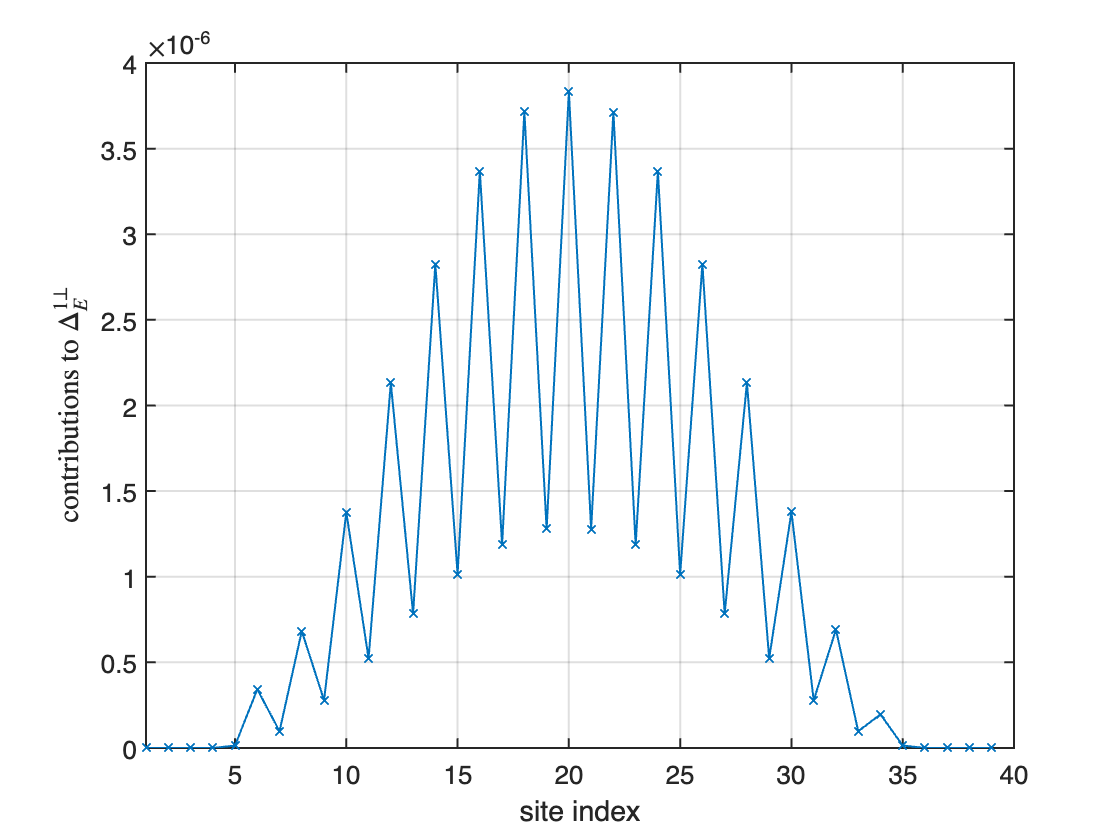

figure;
plot((1:L-1),varE2,'-x','LineWidth',1);
xlim([1 L]);
grid on;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('site index');
ylabel('contributions to $\Delta_{E}^{1\perp}$','Interpreter','latex');

On the other hand, the contributions to $\Delta_E^{1\perp}$ are much smaller than those to $\Delta_E^{2\perp}$. It is because that the Hamiltonian consists of only two-site interaction terms.

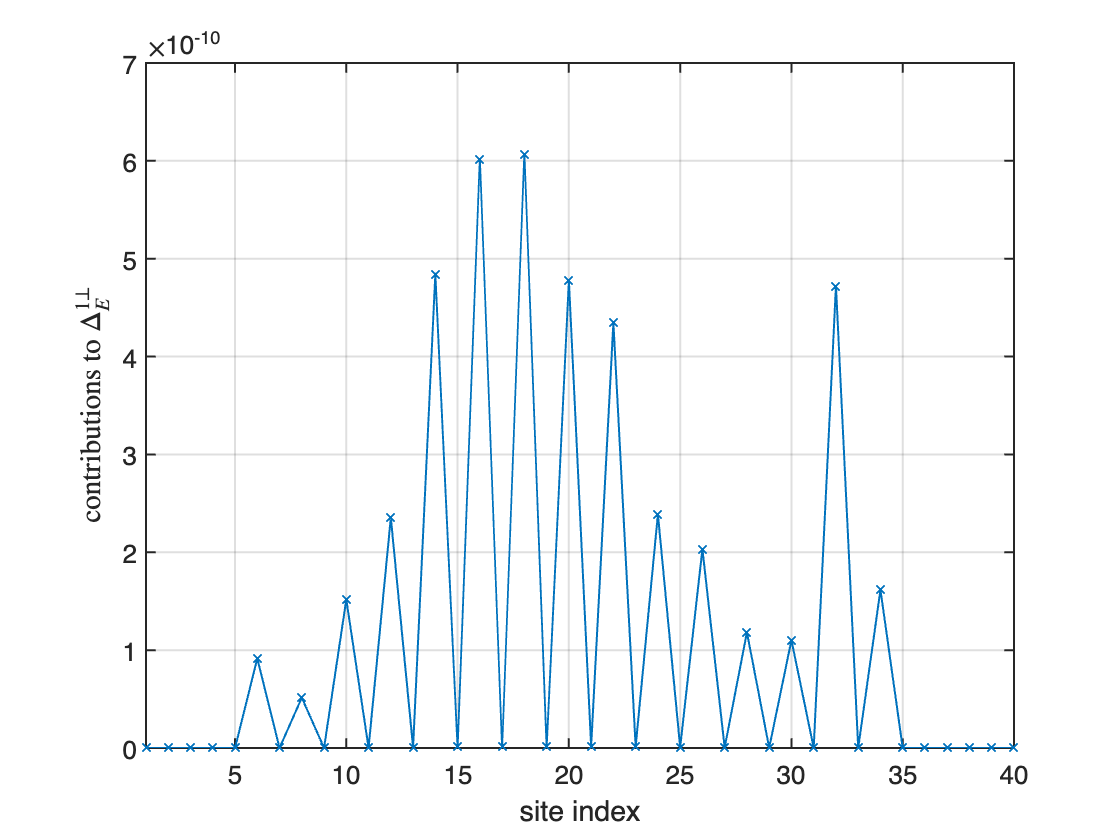

figure;
plot((1:L),varE1,'-x','LineWidth',1);
xlim([1 L]);
grid on;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('site index');
ylabel('contributions to $\Delta_{E}^{1\perp}$','Interpreter','latex');

## Exercise (b): Extrapolate the ground-state energy as a function of the two-site variance

Repeat the calculation demonstrated above, for different values of `Nkeep`. Analyze how the ground-state energy scales with the two-site variance. Extrapolate the energy towards the limit of vanishing variance, to estimate the "numerically exact" value of the ground-state energy.

## Exercise (c): Hubbard chain

Let's consider the Hubbard chain, i.e., the Hubbard model on a one-dimensional lattice, whose Hamiltonian is given by


$$\hat{H} = -t \sum_{i = 1}^{L-1} \sum_{\sigma = {\uparrow},{\downarrow}} ( \hat{c}_{i+1,\sigma}^\dagger \hat{c}_{i,\sigma} + \hat{c}_{i,\sigma}^\dagger \hat{c}_{i+1,\sigma} ) + \sum_{i = 1}^{L} \left( \frac{U \hat{n}_{i} (\hat{n}_{i} - 1)}{2} - \mu \hat{n}_{i} \right)$$


where $\hat{c}_{i\sigma}^\dagger$ creates a particle of spin-$\sigma$ at site $i$, and $\hat{n}_{i} = \sum_{\sigma = \uparrow,\downarrow}\hat{c}_{i\sigma}^\dagger \hat{c}_{i\sigma}$ counts the number particles at site $i$. Here we choose the chain length $L = 30$, the hopping amplitude $t = 1$, and the interaction strength $U = 8$. By choosing $\mu = U/2$, the system is particle-hole symmetric. Perform the DMRG ground-state search for this system for different values of `Nkeep`. Extrapolate the ground-state energy towards the limit of vanishing two-site energy variance.

Note that the Hubbard model is much harder to solve than the XY spin chain, since the minimization of the kinetic energy and that of the interaction energy compete. So it's possible that the variational optimization can be trapped in local minima. To avoid this you may consider (i) using the 2-site DMRG and (ii) performing the calculations in the increasing order of `Nkeep`, taking the result of the previous iteration (for smaller `Nkeep`) as the input to the later iteration (for larger `Nkeep`).